# Vectors i Valors Propis

#### Métode de la Potència

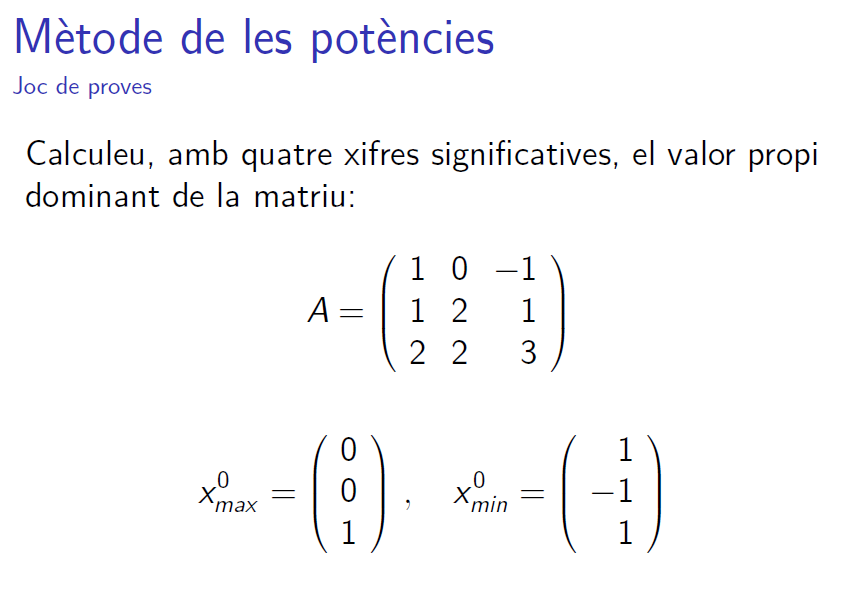

A = [1 0 -1; 1 2 1; 2 2 3]

A =      1     0    -1
     1     2     1
     2     2     3


%  Polinomi característic de la matriu A
p = poly(A)

p =     1.0000   -6.0000   11.0000   -6.0000


% Arrels, valors propis
vaps = roots(p)

vaps =     3.0000
    2.0000
    1.0000


#### Vector propi de valor propi de módul máxim

A = [1 0 -1; 1 2 1; 2 2 3];
v = [0 0 1]'

v =      0
     0
     1


k = 0;
control = 1;
tol = eps;
while (control > tol && k < 50) 
    u = A\v;
    %mk = mk = u'*A*u/(u'*u);
    %mk = sum(u)/sum(v);
    mk = u'*A*u/(u'*u);
    v = u/norm(u, 'inf');
    k = k+1;
    control = norm(A*v - mk*v);
end
control 

control = 0

k % iteracions

k = 35

mk % valor propi

mk = 1

v % vector propi

v =      1
    -1
     0


#### Vector propi de valor propi de módul máxim

A = [1 0 -1; 1 2 1; 2 2 3];
v = [1 -1 1]';
k = 0;
control = 1;
tol = eps;
B = inv(A);
while (control > tol && k < 50) 
    u = A\v;
    %mk = c
    %mk = sum(u)/sum(v);
    mk = u'*A*u/(u'*u);
    v = u/norm(u, 'inf');
    k = k+1;
    control = norm(A*v - 1/mk*v);
end
control % tol

control = 0

k % iteracions

k = 34

1/mk % valor propi

ans = 1

v % vector propi

v =      1
    -1
     0


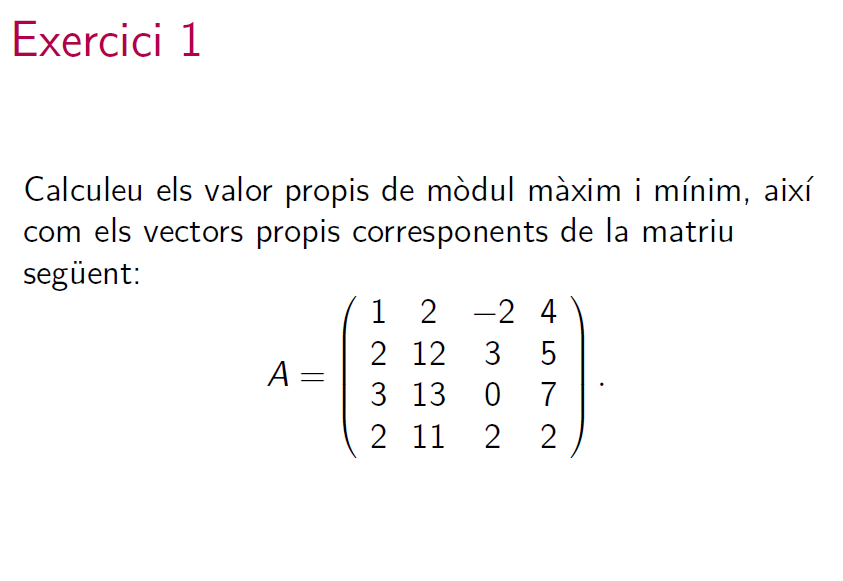

% de modul maxim
A = [1 2 -2 4; 2 12 3 5; 3 13 0 7; 2 11 2 2];
v = [0 0 1 -1]';
p = poly(A);
vaps = roots(p);
k = 0;
control = 1;
tol = eps;
B = inv(A);
while (control > tol && k < 50) 
    u = A\v;
    mk = u'*A*u/(u'*u);
    v = u/norm(u, 'inf');
    k = k+1;
    control = norm(A*v - 1/mk*v);
end
k

k = 50

mk

mk = 0.0122

v

v =    -1.0000
    0.2257
   -0.2501
    0.0090


% de modul maxim
A = [1 2 -2 4; 2 12 3 5; 3 13 0 7; 2 11 2 2];
v = [1 -1 1 0]';
p = poly(A);
vaps = roots(p);
k = 0;
control = 1;
tol = eps;
B = inv(A);
while (control > tol && k < 50) 
    u = A\v;
    mk = u'*u/(u'*A*u);
    v = u/norm(u, 'inf');
    k = k+1;
    control = norm(A*v - 1/mk*v);
end
k

k = 8

mk

mk = 81.9299

v

v =    -1.0000
    0.2257
   -0.2501
    0.0090


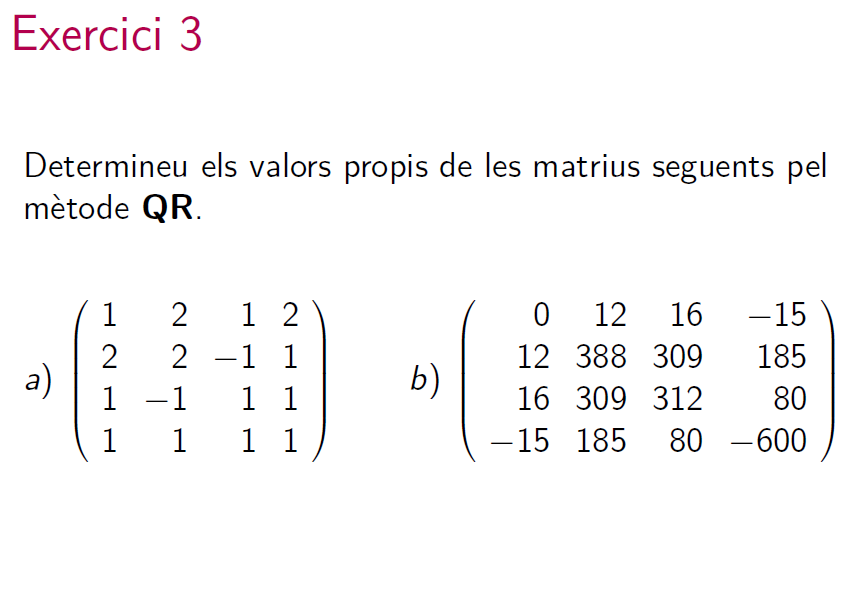

clearvars
A = [1 2 1 2; 2 2 -1 1; 1 -1 1 1; 1 1 1 1];
p = poly(A), valors = roots(p)

p =     1.0000   -5.0000   -1.0000   14.0000    6.0000


valors =     4.4495
    2.3028
   -1.3028
   -0.4495



B = hess(A);
k = 0;
control = 1;
while (control > eps && k < 50)
    [Q,R] = qr(B);
    k = k+1;
    % Q*R-B
    B = R*Q;
    control = norm(tril(B, -1), 2);
end
B  %% despres del canvi de base, la diagonal inferior queda zero

B =     4.4495   -0.1151   -0.0247   -0.7493
    0.0000    2.3028    0.0962    0.3249
         0    0.0000   -1.3028   -0.5566
         0         0    0.0000   -0.4495


k

k = 50

control

control = 3.0228e-11

Apartat b)

clearvars
A = [0 12 16 -15; 12 388 309 185; 16 309 312 80; -15 185 80 -600];
p = poly(A), valors = roots(p)

p = 	1.0e+07 *

    0.0000   -0.0000   -0.0436    1.9408    1.4266


valors =   690.3367
 -634.6322
   45.0188
   -0.7233



B = hess(A);
k = 0;
control = 1;
while (control > eps && k < 50)
    [Q,R] = qr(B);
    k = k+1;
    % Q*R-B
    B = R*Q;
    control = norm(tril(B, -1), 2);
end
B  %% despres del canvi de base, la diagonal inferior queda zero

B =   690.3297   -3.0535   -0.0000    0.0000
   -3.0535 -634.6251   -0.0000    0.0000
         0   -0.0000   45.0188    0.0000
         0         0   -0.0000   -0.7233


k

k = 50

control

control = 3.0535